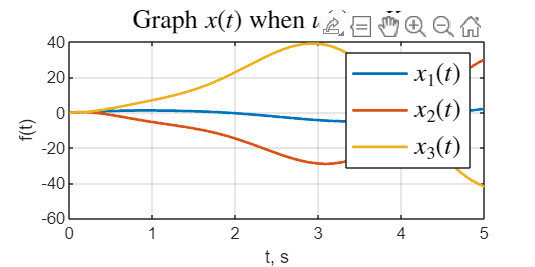

open_system('task_1_sim');
set_param('task_1_sim/x', 'VariableName', 'x')
set_param('task_1_sim/u', 'VariableName', 'u')
set_param('task_1_sim/w_f', 'VariableName', 'w_f')
set_param('task_1_sim/z', 'VariableName', 'z')

K1 = [-6.5000 -0.2500 0.2500];
%K2 = [-11.8500 -2.1000 7.2000 -4.4000];
%K1 = [0 0 0];
K2 = [0 0 0 0];

out = sim('task_1_sim');

%{
figure('Position', [100 100 800 400])
plot(out.u,'-', 'LineWidth',1.5);
hold on
K2 = [-11.8500 -2.1000 7.2000 -4.4000];
out = sim('task_1_sim');
plot(out.u,'-', 'LineWidth',1.5);
grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u(t) = K_1x$', '$u(t) = K_1x + K_2w_f$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off
%}
%{
figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);
hold on
K2 = [-11.8500 -2.1000 7.2000 -4.4000];
out = sim('task_1_sim');
plot(out.z,'-', 'LineWidth',1.5);
grid()
title('Graph $z(t)$','Interpreter','latex',  'FontSize', 14)
legend('$z(t): u(t) = K_1x$', '$z(t): u(t) = K_1x+ K_2w_f$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off
%}

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5)
grid()
title('Graph $x(t)$ when $u(t) = K_1x$','Interpreter','latex',  'FontSize', 14)
legend('$x_{1}(t)$', '$x_{2}(t)$', '$x_{3}(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

%{
figure('Position', [100 100 800 400])
plot(out.w_f,'-', 'LineWidth',1.5)
grid()
title('Graph $w_f(t)$ when $u(t) = K_1x$','Interpreter','latex',  'FontSize', 14)
legend('$w_{f1}(t)$', '$w_{f2}(t)$', '$w_{f3}(t)$', '$w_{f4}(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%}